# 2D Compressible

### Set parameters

N = 64;
inner_radius = 5;
outer_radius = 100;
density = 1.225;
u_sound = 340;
x_velocity = 0.1 * u_sound;
y_velocity = 0 * u_sound;
gamma = 1.4;
C2tref = 0.51;
mu = 1.8e-5;
max_iter = 20;

#### Generate grids

[x, y, r, dtheta] = gen_donut_mesh2(inner_radius, outer_radius, N);

#### Initialization

l = length(r);
P = (density * u_sound * u_sound) / gamma .* ones(N, l);
rho = density .* ones(N, l);
rhou = [zeros(N, 1), density * x_velocity .* ones(N, l - 1)];
rhov = [zeros(N, 1), density * y_velocity .* ones(N, l - 1)];
E = P ./ (gamma - 1) .* ones(1,l) + 0.5 .* (rhou .* rhou + rhov .* rhov) ./ rho;
u = rhou ./ rho;
v = rhov ./ rho;

#### Calculate radius

r_in = r(1:end - 2);
r_in = ones(N, 1) * r_in;
r_h = r(2:end - 1);
r_h = ones(N,1) * r_h;
r_out = r(3:end);
r_out = ones(N, 1) * r_out;

#### Calculate norms

nrx = x(:, 3:end) - x(:, 1:end - 2);
nry = y(:, 3:end) - y(:, 1:end - 2);
norm = sqrt(nrx .* nrx + nry .* nry);
nrx = nrx ./ norm;
nry = nry ./ norm;
ntcx = circshift(x(:, 2:end - 1), 1) - x(:, 2:end - 1);
ntcy = circshift(y(:, 2:end - 1), 1) - y(:, 2:end - 1);
norm = sqrt(ntcx .* ntcx + ntcy .* ntcy);
ntcx = ntcx ./ norm;
ntcy = ntcy ./ norm;
ntccx = circshift(x(:, 2:end - 1), -1) - x(:, 2:end - 1);
ntccy = circshift(y(:, 2:end - 1), -1) - y(:, 2:end - 1);
norm = sqrt(ntccx .* ntccx + ntccy .* ntccy);
ntccx = ntccx ./ norm;
ntccy = ntccy ./ norm;

## Solving

for iter = 1:max_iter

Record values from this step

rho_last = rho;
rhou_last = rhou;
rhov_last = rhov;
E_last = E;

Calculate F and G

F1 = rhou;
F2 = rhou .* u + P;
F3 = rhou .* v;
F4 = (E + P) .* u;
G1 = rhov;
G2 = rhov .* u;
G3 = rhov .* v + P;
G4 = (E + P) .* v;

Calculate local difference

[udx, udy] = local_diff(u, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);
[vdx, vdy] = local_diff(v, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);
[Edx, Edy] = local_diff(E, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);

Calculate dynamic viscosity

T = P .* gamma ./ rho;
T_Ts = T ./ 273;
viscosity = mu .* T_Ts .^ 1.5 .* (T_Ts + C2tref) ./ (1 + C2tref);
artificial_viscosity = 1000;
viscosity = viscosity + artificial_viscosity;

Calculate R and S

R2 = 2 / 3 .* viscosity .* (2 .* udx - vdy);
R3 = viscosity .* (udy + vdx);
R4 = u .* R2 + v .* R3 - viscosity .* Edx;
S2 = R3;
S3 = 2 / 3 .* viscosity .* (2 .* vdy - udx);
S4 = u .* S2 + v .* S3 - viscosity .* Edy;

Calculate local time step

OMEGA = 1.0;
ALPHA = 8.0;
dr = (r_out - r_in) ./ 2;
v_sound = sqrt(P .* gamma ./ rho) .* 340;
sx = 0.5 .* (abs((r_out + r_in) .* dtheta .* nry) + abs(dr .* ntcy) + abs(dr .* ntccy));
sy = 0.5 .* (abs((r_out + r_in) .* dtheta .* nrx) + abs(dr .* ntcx) + abs(dr .* ntccx));
vol = 0.5 .* dr .* (r_out + r_in) .* dtheta;
sx = [zeros(N, 1) sx zeros(N, 1)];
sy = [zeros(N, 1) sy zeros(N, 1)];
vol = [zeros(N, 1) vol zeros(N, 1)];
TERM_C = (abs(u) + v_sound) .* sx + (abs(v) + v_sound) .* sy;
TERM_D = 2.0 .* viscosity .* vol ./ (sx + sy);
dt = vol .* OMEGA ./ (TERM_C + TERM_D * ALPHA);

#### Lax Wendroff

rho = Lax_Wendroff_disk(rho, F1, G1, dt, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);
rhou = Lax_Wendroff_disk(rhou, F2 - R2, G2 - S2, dt, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);
rhov = Lax_Wendroff_disk(rhov, F3 - R3, G3 - S3, dt, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);
E = Lax_Wendroff_disk(E, F4 - R4, G4 - S4, dt, r_in, r_h, r_out, dtheta, nrx, nry, ntcx, ntcy, ntccx, ntccy);

Smooth

SIGMA2 = 200;
SIGMA4 = 50;
rho = smooth(rho, rho - rho_last, dt, r_out, r_in, dtheta, SIGMA2, SIGMA4);
rhou = smooth(rhou, rhou - rhou_last, dt, r_out, r_in, dtheta, SIGMA2, SIGMA4)

rhou =          0   41.5996   41.4589   41.6513   41.6513   41.6511   41.6510   41.6509   41.6509   41.6508   41.6507   41.6506   41.6506   41.6505   41.6505   41.6504   41.6504   41.6504   41.6503   41.6503   41.6503   41.6502   41.6502   41.6502   41.6502   41.6502   41.6501   41.6501   41.6501   41.6501   41.6502   41.6521   41.6500
         0   41.6028   41.4706   41.6512   41.6512   41.6511   41.6510   41.6509   41.6508   41.6507   41.6507   41.6506   41.6505   41.6505   41.6504   41.6504   41.6504   41.6503   41.6503   41.6503   41.6502   41.6502   41.6502   41.6502   41.6502   41.6501   41.6501   41.6501   41.6501   41.6501   41.6502   41.6520   41.6500
         0   41.6065   41.4837   41.6510   41.6510   41.6509   41.6508   41.6508   41.6507   41.6506   41.6506   41.6505   41.6505   41.6504   41.6504   41.6504   41.6503   41.6503   41.6503   41.6502   41.6502   41.6502   41.6502   41.6502   41.6501   41.6501   41.6501   41.6501   41.6501   41.6501   41.6502   41.6519   41.6500


rhov = smooth(rhov, rhov - rhov_last, dt, r_out, r_in, dtheta, SIGMA2, SIGMA4);
E = smooth(E, E - E_last, dt, r_out, r_in, dtheta, SIGMA2, SIGMA4);

Boundary condition

T = P .* gamma ./ rho;
P = extrapolate_boundary(P);
T = extrapolate_boundary(T);
rho(:, 1) = P(:, 1) .* gamma ./ T(:, 1);
E(:, 1) = P(:, 1) ./ (gamma - 1);

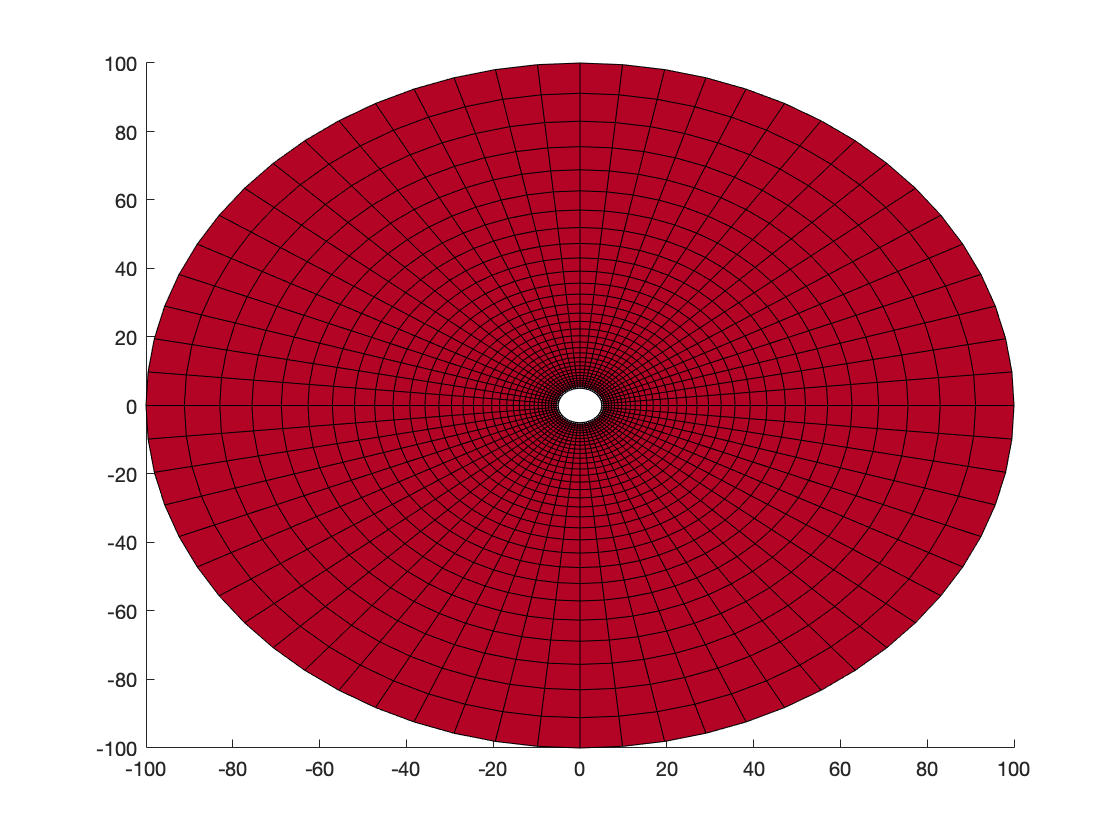

plot_2d(rhou)

end